- Multivariate  Random Variables  

    1)  Joint probablity distribution $F_{XY} (x,y)$

          
$$F_{XY}(X,Y) = Prob(X \le x \ , Y\le y)$$


     2) Joint probability density function $f_{XY} (x,y)$


$$f_{XY}(x,y) = \frac{\partial F_{XY} (x,y)}_{\partial x \partial y$$
 

        or 


$$F_{XY}(x,y) = probability \{X\le x, \ Y \le y\} \\
= \int_{-\infty}^{x} \int_{-\infty}^{\infty} f(x,y) dx dy$$


     3) marginal probability density 


$$f(x) = \int_{-\infty}^{\infty} f(x,y) dy$$


     4) Conditional probabilty dendity


$$f(x|y) = f(x,y) / f(y)$$


-   Examples_1


$$f(x,y)=\begin{cases}
    1 & \text{if   0<x<1, -1/2<y<1/2 }.\\
    0, & \text{otherwise}.
  \end{cases}$$


            -. Distribution function 


$$F(x,y) = \int _{-\infty} ^{y}\int_{-\infty}^{x} f(x,y)dxdy \\
= \int_{-\infty}^{y} \int_{0}^{x}1dx dy \\
=\int_{-\infty}^{y} x dy \\
=x \int_{-1/2}^{y} (1)dy \\
=x(y+1/2), \ \ \ 0<x<1 , -1/2<y <1/2 
$$


                 -.Probability : 


$$ Prob \{ X \le -1, Y \le  -1 \} =F(-1,-1) =0$$



$$Prob  \{  X\le  0.5, y\le =0 \} = F(0.5, 0)=1/4$$



$$Prob  \{  X\le  0.5, y\le =2\} = F(0.5, 2)=1/2$$


                -.Marginal probability


$$f(x) = \int_{-\infty}^{\infty} f(x,y) dy \\
= \int_{-1/2}^{1/2} 1 dy  \\=1 , 0\le x\le 1$$


                -Conditional Prob


$$f(x|y) = \frac{f(x,y)}_{f(y)} = 1/1 =1 , $$


%% comment:

    If RVs  are independent,  


$$f(x,y) = f(x)f(y)$$
    

   Further by Bayes rule


$$f(x|y) = \frac{f(x,y)}_{f(y)} =f(x)$$
    

                                                                                                           %%

-        In general case , $Z $ is a function of $(X,Y)$ as 


$$Z= X+Y \ or \ Z= XY \ or Z =X^2Y,...$$


              Then each of the joint pdf of $Z$ is 


$$f_{Z} (z)  = f_{XY} (x,y) $$


            different so that it should be calculate separately.

-       Simple linear case


$$Z = X + Y$$


           1) Expectation of $Z$

              - $E[X]$


$$E[Z] =\int_{-\infty}^{\infty} zf(z) dz = E[X + Y]
$$


               Since , $E[ .] $ is a linear operator,


$$E[X+Y] = E[X] + E[Y]$$


          2)  code example

       Let us generate two uniform RVs. 

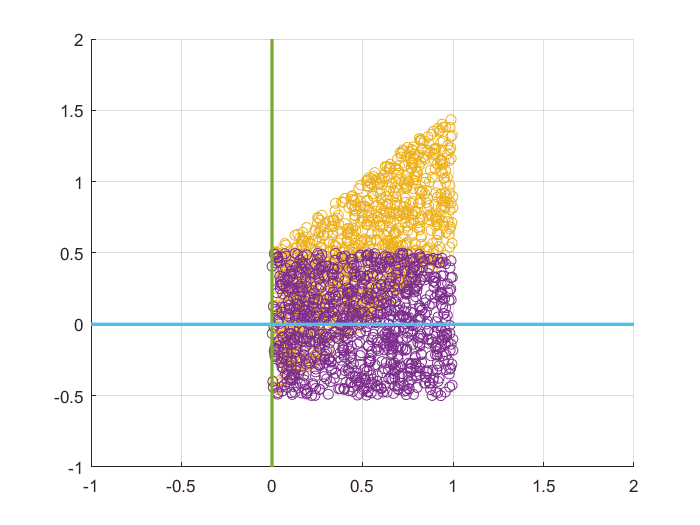

clear all;
rng('default')
n = 1000; 
x = rand(n,1);         % uniform 
% x = randn(n,1);      % gauss
y = rand(n,1)- 1/2;    
% y = randn(n,1);
scatter(x,y)
axis([-1 2 -1 2])
% histogram2(x,y,'DisplayStyle', 'tile')
hold on ; grid on
plot([0 0], ylim, 'linewidth',2)                 % Dashed Vertical Line at x=0
plot(xlim, [0 0], 'linewidth',2)                 % Dashed Horizontal Line at y=0

  Now generate a random variable of the sum of two.

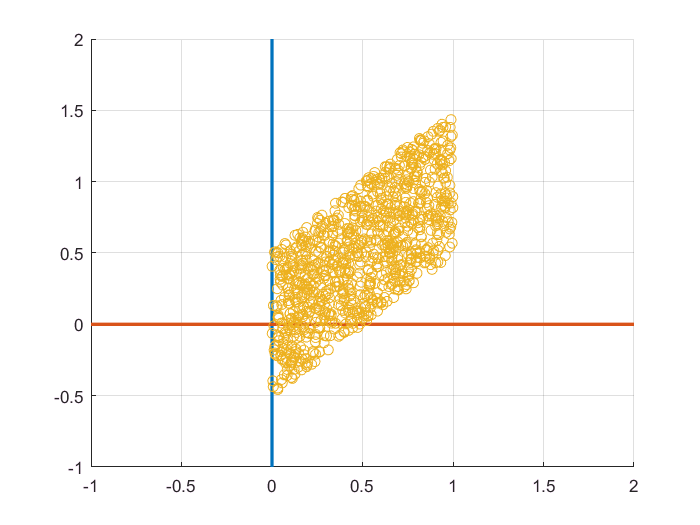

z = x+y;
figure( )
axis([-1 2 -1 2])
hold on ; grid on
plot([0 0], xlim, 'linewidth',2)                 % Dashed Vertical Line at x=0
plot(ylim, [0 0], 'linewidth',2)                 % Dashed Horizontal Line at y=0
scatter(x,z)

mean(z)

ans = 0.4989

mean(x) + mean(y)

ans = 0.4989

% variance
var(x)

ans = 0.0802

var(y)

ans = 0.0814

var(x)+var(y)

ans = 0.1616

var(z)

ans = 0.1620

           - Co-Variance 


$$E[(Z -E[Z])^2] = E[(X+Y)^2 - (E[X+Y])^2] $$


            Simplify the equation as (Chech it !!)


$$E[(Z- (E[Z]))^2  = E[(X -(E[X]))^2] + E[(Y -(E[Y]))^2] + E[(X -E[X])(Y-E[Y])] \\
= \sigma_X^2 + \sigma _Y ^2 -2Cov(X,Y)$$


  where 


$$Cov(X,Y) = E[(X-E[X])(Y-E[Y])] \\
 \\ =\int_{-\infty}^{\infty} \int_{-\infty}^{\infty}(X-E[X])(Y-E[Y])f(X,Y)dxdy \\ =
 \int_{-\infty}^{\infty}(X-E[X])f(x)dx \int_{-\infty}^{\infty}(Y-E[Y])f(y)dx $$


 If $(X,Y)  $**is independent**, then 


$$Cov(X,Y) \\ =\int_{-\infty}^{\infty} \int_{-\infty}^{\infty}(X-E[X])(Y-E[Y])f(X,Y)dxdy \\ =
 \int_{-\infty}^{\infty}(X-E[X])f(x)dx \int_{-\infty}^{\infty}(Y-E[Y])f(y)dx $$


And 


$$\int_{-\infty}^{\infty} (x - E[X])f(x)dx = 0$$


Hence 


$$Cov(X,Y) = 0$$


  - terminology : Un - correlated $(X,Y)$ : 


$$E[(X-E[X])(Y-E[Y])] =0 \equiv E[XY]=E[X]E[Y]
$$


 Hence Independent implies un-correlated but not vice versa

- In matlab command, "cov" generates the variance and their covariance simultaneously as


$$cov(X,Y)= \left[\matrix{ E[(X-E[X])^2 ]& E[(X-E[X])(Y-E[Y])]  \cr  E[(X-E[X])(Y-E[Y])] & E[(Y-E[Y])^2 ]} \right]$$


cov(x,y)

ans =     0.0802    0.0002
    0.0002    0.0814


 Here  in uniform RV in $[a ,b]$, the variance   $E[(X-E[X])^2]$  is 


$$\frac{(b-a)^2}_{12}$$


hence 


$$0.0802  \sim 1/12 = 0.0833$$


and the covariance E[(X-E[X])(Y-E[Y])]  is 


$$-0.0005 \sim  0$$


which implies $(X,Y)$ is un-correlated. to check , code in the above.